% Final Project - ENGR 25, Fall 2021
% Darren Ho, Seth Miu

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%       Part 3       %%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

clear; clc; close all;

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%      Alameda County       %%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%%%%%%%%%%%%%%%%%%%%%%%
%%    Import Data    %%
%%%%%%%%%%%%%%%%%%%%%%%

warning('off')

Alameda_df = readtable('Data_Part1_v4.xlsx','Sheet','Alameda');
Alameda_wf = groupsummary(Alameda_df(:,1:end-1),'Date','week','sum');


% Assume 80% of cases undetected during initial outbreak
% Source:
% https://www.science.org/doi/full/10.1126/scitranslmed.abc1126

initialPositive = Alameda_wf.sum_PositiveTests(1)

initialPositive = 4

infectedPop = initialPositive * 5

infectedPop = 20


alameda_pop = Alameda_df.TotalPopulation(1) % population at day 0 of the outbreak

alameda_pop = 1685886

pop0 = [1-(infectedPop/alameda_pop),infectedPop/alameda_pop,0]; % pop ratio of s(t),i(t),r(t)


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%               Step 1               %%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

mu = 1/3;
beta = 1/2;

% Euler's Method
dt = 1;			                % let delta t = 1 day
tspan = 1:dt:height(Alameda_wf.week_Date)*7;
POP(:,1) = pop0;		        % POP is the matrix of population data
for i = 1:length(tspan)-1		% forward euler in a for loop
    POP(:,i+1) = POP(:,i) + dt * SIRmodel(tspan, POP(:,i),beta,mu);
end

[t,pop] = ode45(@(t,pop0)SIRmodel(t,pop0,beta,mu),tspan,pop0);
[maxval_Infect, maxindex]= max(pop(:,2))

maxval_Infect = 0.0630

maxindex = 62

maxInfectDay = tspan(maxindex)

maxInfectDay = 62

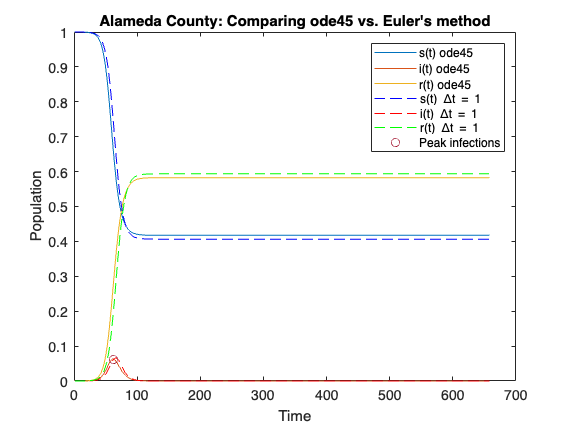


plot(tspan,pop(:,1),tspan,pop(:,2),tspan,pop(:,3)) 
hold on
plot(tspan,POP(1,:),'--b',tspan,POP(2,:),'--r',tspan,POP(3,:),'--g',maxInfectDay,maxval_Infect,'o') 
hold off
xlabel('Time')
ylabel('Population')
title('Alameda County: Comparing ode45 vs. Euler''s method')
legend('s(t) ode45','i(t) ode45','r(t) ode45','s(t) \Deltat = 1', 'i(t) \Deltat = 1', 'r(t) \Deltat = 1','Peak infections')

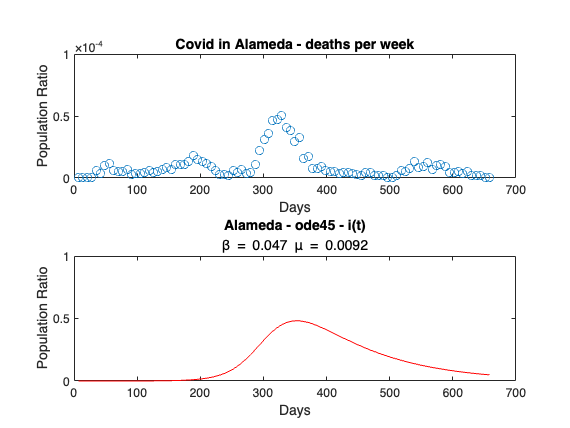

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%               Step 2               %%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% Finding best-fit beta and mu values

mu = 0.0092;
beta = 0.0466;

tspan = 7 * (1:length(Alameda_wf.week_Date));

% Plot the data and the model fit together:
figure
subplot(2,1,1) % plotting the given data
plot(tspan,Alameda_wf.sum_Deaths/alameda_pop,'o')
title('Covid in Alameda - deaths per week')
xlabel('Days'),ylabel('Population Ratio')
ylim([0 .0001])

subplot(2,1,2) % plotting the ode45 model
[t,pop] = ode45(@(t,pop0)SIRmodel(t,pop0,beta,mu),tspan,pop0);
plot(tspan,pop(:,2),'r')
ylim([0 1])
xlabel('Days')
ylabel('Population Ratio')
title('Alameda - ode45 - i(t)',['\beta = ',num2str(beta,2),' \mu = ',num2str(mu,2)])

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%               Step 3               %%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% Finding two Ro values

% time span approaching arbitrarily large # of days
tspan = 0:dt:9999;

[t,pop] = ode45(@(t,pop0)SIRmodel(t,pop0,beta,mu),tspan,pop0);

sinf = min(pop(:,1)); 

Ro1 = log(sinf) / (sinf-1)

Ro1 = 5.0679

Ro2 = beta/mu

Ro2 = 5.0652

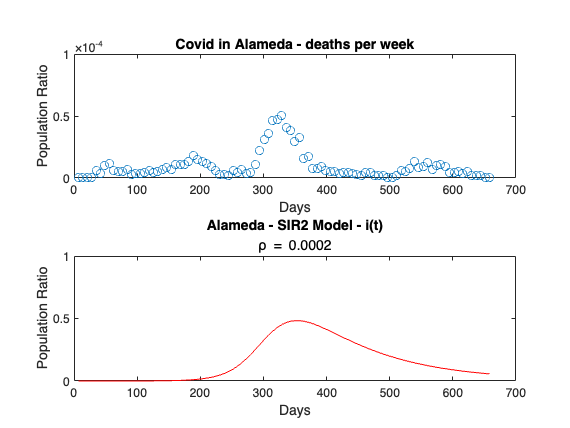

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%               Step 4               %%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%%%%%%%%%%%%%
%%  A / B  %%
%%%%%%%%%%%%%

% Finding best-fit rho value using previous beta and mu
rho = 0.0002;

tspan = 7 * (1:length(Alameda_wf.week_Date));

% Plot the data and the model fit together:
figure
subplot(2,1,1) % plotting the given data
plot(tspan,Alameda_wf.sum_Deaths/alameda_pop,'o')
title('Covid in Alameda - deaths per week')
xlabel('Days'),ylabel('Population Ratio')
ylim([0 .0001])

subplot(2,1,2) % plotting the ode45 mode
% l
[t,pop] = ode45(@(t,pop0)SIR2model(t,pop0,beta,mu,rho),tspan,pop0);
plot(tspan,pop(:,2),'r')
ylim([0 1])
xlabel('Days')
ylabel('Population Ratio')
title('Alameda - SIR2 Model - i(t)',['\rho = ',num2str(rho,2)])

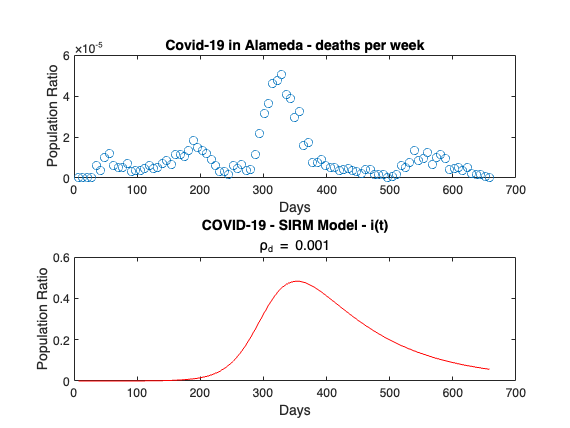

%%%%%%%%%%%%%
%%  C / D  %%
%%%%%%%%%%%%%

pop0 = [1-(infectedPop/alameda_pop),infectedPop/alameda_pop,0,0]; % pop ratio of s(t),i(t),r(t), m(t)

% Finding best-fit rho-d value
rho_d = 0.001033;

% Alameda 
figure
subplot(2,1,1)
plot((1:length(Alameda_wf.week_Date))*7, (Alameda_wf.sum_Deaths)/ alameda_pop,'o')
title('Covid-19 in Alameda - deaths per week')
xlabel('Days'),ylabel('Population Ratio')

% ode45 model
subplot(2,1,2)
[t,pop] = ode45(@(t,pop0)SIRMmodel(t,pop0,beta,mu,rho,rho_d),tspan,pop0);
plot(tspan,pop(:,2),'r')

xlim([0 700])
xlabel('Days')
ylabel('Population Ratio')
title('COVID-19 - SIRM Model - i(t)',['\rho_d = ',num2str(rho_d,2)])

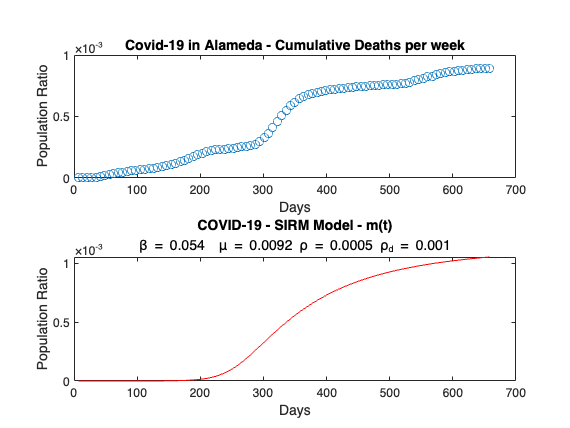

%%%%%%%%%%%%%%%%%
%%  E / F / G  %%
%%%%%%%%%%%%%%%%%

% Finding best-fit all parameters:
mu = 0.0092;
beta = 0.0544;
rho = 0.0005;
rho_d = 0.001033;


% Alameda DEATHS:
figure
subplot(2,1,1)
plot((1:length(Alameda_wf.week_Date))*7, cumsum(Alameda_wf.sum_Deaths)/ alameda_pop,'o')
title('Covid-19 in Alameda - Cumulative Deaths per week')
xlabel('Days'),ylabel('Population Ratio')

% ode45 model
subplot(2,1,2)
[t,pop] = ode45(@(t,pop0)SIRMmodel(t,pop0,beta,mu,rho,rho_d),tspan,pop0);
plot(tspan,pop(:,4),'r')

xlim([0 700])
xlabel('Days')
ylabel('Population Ratio')
title('COVID-19 - SIRM Model - m(t)', ...
    ['\beta = ',num2str(beta,2),' ' ...
    ' \mu = ',num2str(mu,2), ...
    ' \rho = ',num2str(rho,2), ...
    ' \rho_d = ',num2str(rho_d,2)])

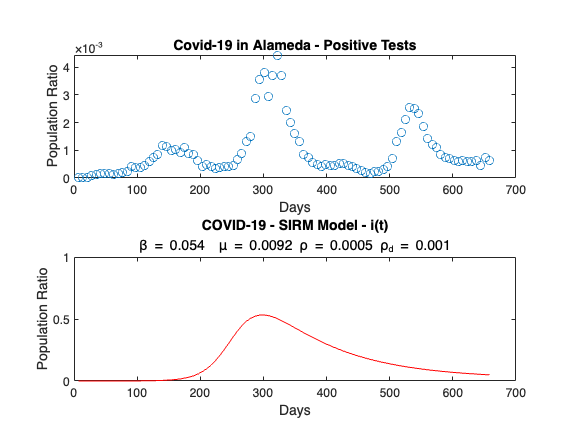


% Alameda Infections
figure
subplot(2,1,1)
plot((1:length(Alameda_wf.week_Date))*7, Alameda_wf.sum_PositiveTests/ alameda_pop,'o')
title('Covid-19 in Alameda - Positive Tests')
xlabel('Days'),ylabel('Population Ratio')
% ode45 model
subplot(2,1,2)
[t,pop] = ode45(@(t,pop0)SIRMmodel(t,pop0,beta,mu,rho,rho_d),tspan,pop0);
plot(tspan,pop(:,2),'r')
xlim([0 700])
ylim([0 1])

xlabel('Days')
ylabel('Population Ratio')
title('COVID-19 - SIRM Model - i(t)', ...
    ['\beta = ',num2str(beta,2),' ' ...
    ' \mu = ',num2str(mu,2), ...
    ' \rho = ',num2str(rho,2), ...
    ' \rho_d = ',num2str(rho_d,2)])

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%               Step 5               %%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

tspan = 1:9999;
[t,pop] = ode45(@(t,pop0)SIRMmodel(t,pop0,beta,mu,rho,rho_d),tspan,pop0);

[maxval_Infect, maxindex]= max(pop(:,2))

maxval_Infect = 0.5328

maxindex = 292

maxInfectDay = tspan(maxindex)

maxInfectDay = 292

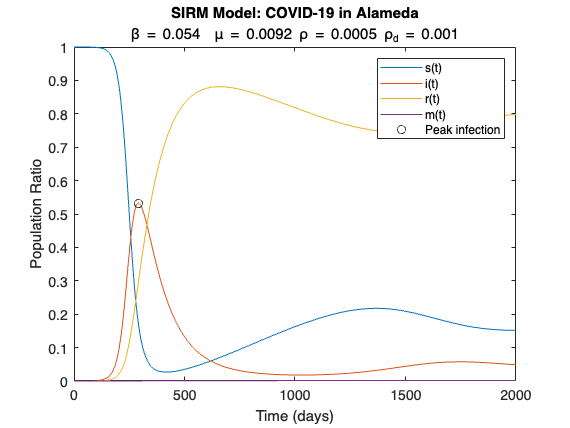


figure

plot(tspan,pop(:,1),tspan,pop(:,2),tspan,pop(:,3),tspan,pop(:,4),maxInfectDay,maxval_Infect,'ok')
xlabel('Time (days)')
ylabel('Population Ratio')
title('SIRM Model: COVID-19 in Alameda', ...
    ['\beta = ',num2str(beta,2),' ' ...
    ' \mu = ',num2str(mu,2), ...
    ' \rho = ',num2str(rho,2), ...
    ' \rho_d = ',num2str(rho_d,2)])

legend('s(t)','i(t)','r(t)','m(t)','Peak infection')
xlim([0 2000])

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%               Step 6               %%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

count_to_enddate = maxInfectDay;

try
    while pop(count_to_enddate,2) > 0.001
        count_to_enddate = count_to_enddate +1;
    end
fprintf('The epidemic take %d days until the infection ratio is below 0.001.',count_to_enddate)

catch
    count_to_enddate = 9999;
    fprintf('The epidemic take over %d days before the infection ratio is below 0.001.',count_to_enddate)
end

The epidemic take over 9999 days before the infection ratio is below 0.001.

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%               Step 7               %%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

Ro = beta/mu

Ro = 5.9130

so = 1/Ro - 0.00001

so = 0.1691

vaccinated = 1 - so

vaccinated = 0.8309


% Assume average COVDID vaccination has 94% success rate
% Source:
% https://www.cdc.gov/mmwr/volumes/70/wr/mm7018e1.htm?s_cid=mm7018e1_w
% https://pubmed.ncbi.nlm.nih.gov/33956782/

herd_immunity = vaccinated / 0.94

herd_immunity = 0.8839

fprintf('At least %.4f of the population must be vaccinated for herd immmunity.', herd_immunity)

At least 0.8839 of the population must be vaccinated for herd immmunity.



%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%      Los Angeles County       %%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%



%%%%%%%%%%%%%%%%%%%%%%%
%%    Import Data    %%
%%%%%%%%%%%%%%%%%%%%%%%

clear; clc; close all;

warning('off')

LA_df = readtable('Data_Part1_v4.xlsx','Sheet','LA');
LA_wf = groupsummary(LA_df(:,1:end-1),'Date','week','sum');


% Assume 80% of cases undetected during initial outbreak
% Source:
% https://www.science.org/doi/full/10.1126/scitranslmed.abc1126

initialPositive = LA_wf.sum_PositiveTests(1)

initialPositive = 9

infectedPop = initialPositive * 5

infectedPop = 45


la_pop = LA_df.TotalPopulation(1) % population at day 0 of the outbreak

la_pop = 10257557

pop0 = [1-(infectedPop/la_pop),infectedPop/la_pop,0]; % pop ratio of s(t),i(t),r(t)


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%               Step 1               %%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

mu = 1/3;
beta = 1/2;

% Euler's Method
dt = 1;			                % let delta t = 1 day
tspan = 1:dt:height(LA_wf.week_Date)*7;
POP(:,1) = pop0;		        % POP is the matrix of population data
for i = 1:length(tspan)-1		% forward euler in a for loop
    POP(:,i+1) = POP(:,i) + dt * SIRmodel(tspan, POP(:,i),beta,mu);
end

[t,pop] = ode45(@(t,pop0)SIRmodel(t,pop0,beta,mu),tspan,pop0);
[maxval_Infect, maxindex]= max(pop(:,2))

maxval_Infect = 0.0630

maxindex = 68

maxInfectDay = tspan(maxindex)

maxInfectDay = 68

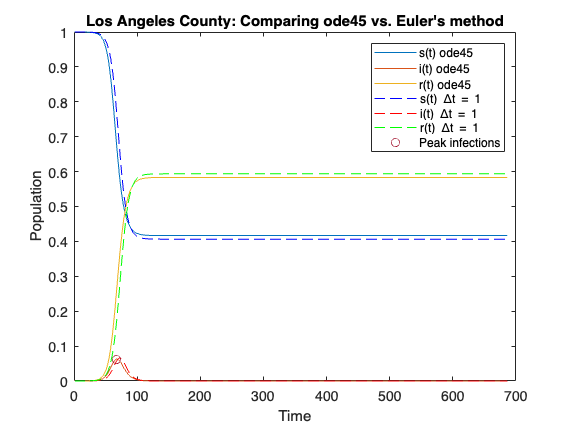


plot(tspan,pop(:,1),tspan,pop(:,2),tspan,pop(:,3)) 
hold on
plot(tspan,POP(1,:),'--b',tspan,POP(2,:),'--r',tspan,POP(3,:),'--g',maxInfectDay,maxval_Infect,'o') 
hold off
xlabel('Time')
ylabel('Population')
title('Los Angeles County: Comparing ode45 vs. Euler''s method')
legend('s(t) ode45','i(t) ode45','r(t) ode45','s(t) \Deltat = 1', 'i(t) \Deltat = 1', 'r(t) \Deltat = 1','Peak infections')

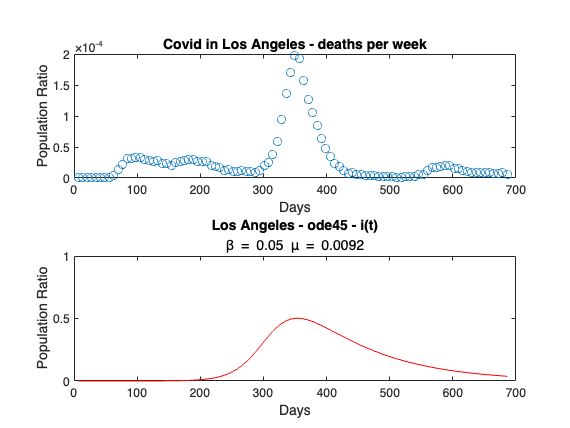

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%               Step 2               %%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% Finding best-fit beta and mu values

mu = 0.0092;
beta = 0.0496;

tspan = 7 * (1:length(LA_wf.week_Date));

% Plot the data and the model fit together:
figure
subplot(2,1,1) % plotting the given data
plot(tspan,LA_wf.sum_Deaths/la_pop,'o')
title('Covid in Los Angeles - deaths per week')
xlabel('Days'),ylabel('Population Ratio')


subplot(2,1,2) % plotting the ode45 model
[t,pop] = ode45(@(t,pop0)SIRmodel(t,pop0,beta,mu),tspan,pop0);
plot(tspan,pop(:,2),'r')
ylim([0 1])
xlabel('Days')
ylabel('Population Ratio')
title('Los Angeles - ode45 - i(t)',['\beta = ',num2str(beta,2),' \mu = ',num2str(mu,2)])

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%               Step 3               %%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% Finding two Ro values

% time span approaching arbitrarily large # of days
tspan = 0:dt:9999;

[t,pop] = ode45(@(t,pop0)SIRmodel(t,pop0,beta,mu),tspan,pop0);

sinf = min(pop(:,1)); 

Ro1 = log(sinf) / (sinf-1)

Ro1 = 5.3962

Ro2 = beta/mu

Ro2 = 5.3913

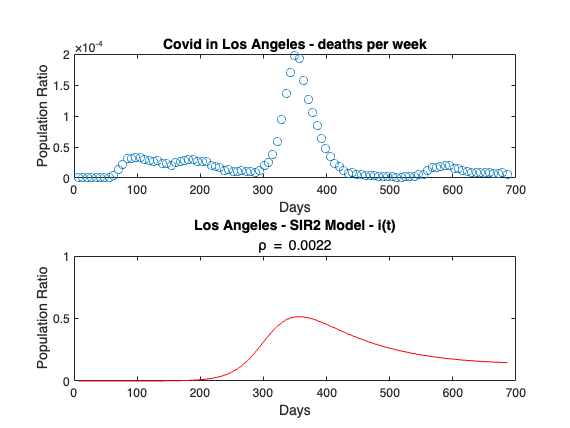

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%               Step 4               %%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%%%%%%%%%%%%%
%%  A / B  %%
%%%%%%%%%%%%%

% Finding best-fit rho value using previous beta and mu
rho = 0.0022;

tspan = 7 * (1:length(LA_wf.week_Date));

% Plot the data and the model fit together:
figure
subplot(2,1,1) % plotting the given data
plot(tspan,LA_wf.sum_Deaths/la_pop,'o')
title('Covid in Los Angeles - deaths per week')
xlabel('Days'),ylabel('Population Ratio')


subplot(2,1,2) % plotting the ode45 mode
% l
[t,pop] = ode45(@(t,pop0)SIR2model(t,pop0,beta,mu,rho),tspan,pop0);
plot(tspan,pop(:,2),'r')
ylim([0 1])
xlabel('Days')
ylabel('Population Ratio')
title('Los Angeles - SIR2 Model - i(t)',['\rho = ',num2str(rho,2)])

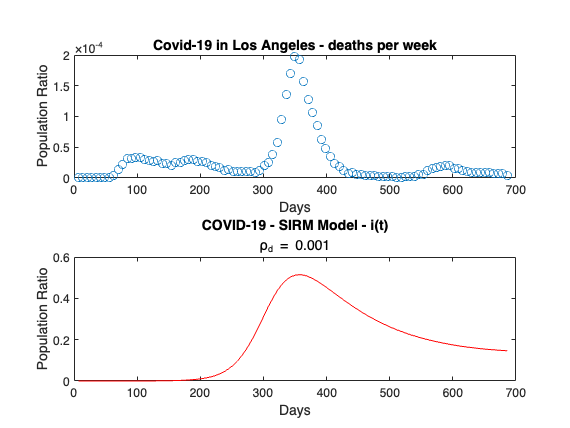

%%%%%%%%%%%%%
%%  C / D  %%
%%%%%%%%%%%%%

pop0 = [1-(infectedPop/la_pop),infectedPop/la_pop,0,0]; % pop ratio of s(t),i(t),r(t), m(t)

% Finding best-fit rho-d value
rho_d = 0.001033;

% Los Angeles 
figure
subplot(2,1,1)
plot((1:length(LA_wf.week_Date))*7, (LA_wf.sum_Deaths)/ la_pop,'o')
title('Covid-19 in Los Angeles - deaths per week')
xlabel('Days'),ylabel('Population Ratio')

% ode45 model
subplot(2,1,2)
[t,pop] = ode45(@(t,pop0)SIRMmodel(t,pop0,beta,mu,rho,rho_d),tspan,pop0);
plot(tspan,pop(:,2),'r')

xlim([0 700])
xlabel('Days')
ylabel('Population Ratio')
title('COVID-19 - SIRM Model - i(t)',['\rho_d = ',num2str(rho_d,2)])

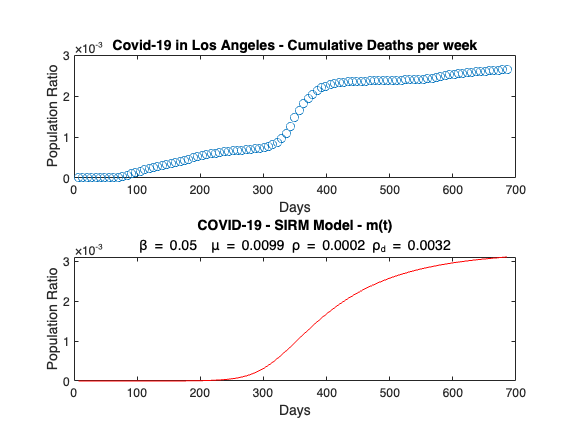

%%%%%%%%%%%%%%%%%
%%  E / F / G  %%
%%%%%%%%%%%%%%%%%

% Finding best-fit all parameters:
mu = 0.0099;
beta = 0.0501;
rho = 0.0002;
rho_d = 0.003185;


% Los Angeles DEATHS:
figure
subplot(2,1,1)
plot((1:length(LA_wf.week_Date))*7, cumsum(LA_wf.sum_Deaths)/ la_pop,'o')
title('Covid-19 in Los Angeles - Cumulative Deaths per week')
xlabel('Days'),ylabel('Population Ratio')

% ode45 model
subplot(2,1,2)
[t,pop] = ode45(@(t,pop0)SIRMmodel(t,pop0,beta,mu,rho,rho_d),tspan,pop0);
plot(tspan,pop(:,4),'r')

xlim([0 700])
xlabel('Days')
ylabel('Population Ratio')
title('COVID-19 - SIRM Model - m(t)', ...
    ['\beta = ',num2str(beta,2),' ' ...
    ' \mu = ',num2str(mu,2), ...
    ' \rho = ',num2str(rho,2), ...
    ' \rho_d = ',num2str(rho_d,2)])

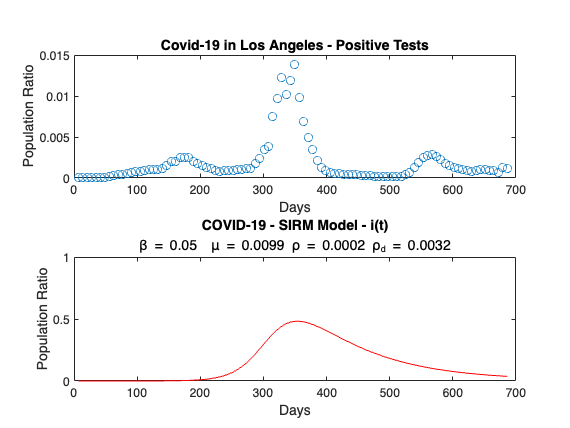


% Los Angeles Infections
figure
subplot(2,1,1)
plot((1:length(LA_wf.week_Date))*7, LA_wf.sum_PositiveTests/ la_pop,'o')
title('Covid-19 in Los Angeles - Positive Tests')
xlabel('Days'),ylabel('Population Ratio')
% ode45 model
subplot(2,1,2)
[t,pop] = ode45(@(t,pop0)SIRMmodel(t,pop0,beta,mu,rho,rho_d),tspan,pop0);
plot(tspan,pop(:,2),'r')
xlim([0 700])
ylim([0 1])

xlabel('Days')
ylabel('Population Ratio')
title('COVID-19 - SIRM Model - i(t)', ...
    ['\beta = ',num2str(beta,2),' ' ...
    ' \mu = ',num2str(mu,2), ...
    ' \rho = ',num2str(rho,2), ...
    ' \rho_d = ',num2str(rho_d,2)])

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%               Step 5               %%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

tspan = 1:9999;
[t,pop] = ode45(@(t,pop0)SIRMmodel(t,pop0,beta,mu,rho,rho_d),tspan,pop0);

[maxval_Infect, maxindex]= max(pop(:,2))

maxval_Infect = 0.4821

maxindex = 348

maxInfectDay = tspan(maxindex)

maxInfectDay = 348

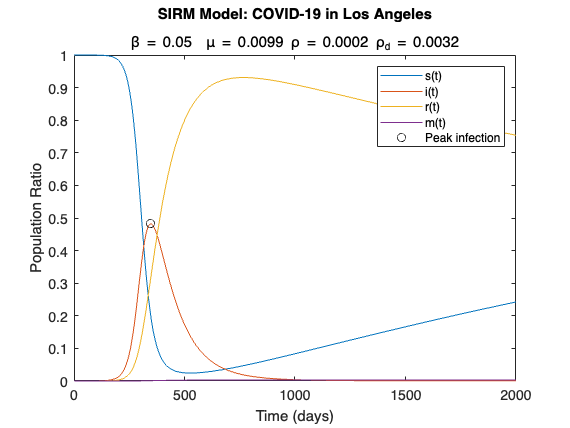


figure

plot(tspan,pop(:,1),tspan,pop(:,2),tspan,pop(:,3),tspan,pop(:,4),maxInfectDay,maxval_Infect,'ok')
xlabel('Time (days)')
ylabel('Population Ratio')
title('SIRM Model: COVID-19 in Los Angeles', ...
    ['\beta = ',num2str(beta,2),' ' ...
    ' \mu = ',num2str(mu,2), ...
    ' \rho = ',num2str(rho,2), ...
    ' \rho_d = ',num2str(rho_d,2)])

legend('s(t)','i(t)','r(t)','m(t)','Peak infection')
xlim([0 2000])

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%               Step 6               %%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

count_to_enddate = maxInfectDay;

try
    while pop(count_to_enddate,2) > 0.001
        count_to_enddate = count_to_enddate +1;
    end
fprintf('The epidemic take %d days until the infection ratio is below 0.001.',count_to_enddate)

catch
    count_to_enddate = 9999;
    fprintf('The epidemic take over %d days until the infection ratio is below 0.001.',count_to_enddate)
end

The epidemic take 1310 days until the infection ratio is below 0.001.

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%               Step 7               %%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

Ro = beta/mu

Ro = 5.0606

so = 1/Ro - 0.00001

so = 0.1976


vaccinated = 1 - so

vaccinated = 0.8024


% Assume average COVDID vaccination has 94% success rate
% Source:
% https://www.cdc.gov/mmwr/volumes/70/wr/mm7018e1.htm?s_cid=mm7018e1_w
% https://pubmed.ncbi.nlm.nih.gov/33956782/

herd_immunity = vaccinated / 0.94

herd_immunity = 0.8536


fprintf('At least %.4f of the population must be vaccinated for herd immmunity.', herd_immunity)

At least 0.8536 of the population must be vaccinated for herd immmunity.

## Diffeq Models

function dpop = SIR2model(t,pop,b,u,p)
% t = time
% pop = population size
% b = beta (chance of infection from contact)
% u = mu (chance of recovery from infection)
% p = rho (chance of being re-infected)


s = pop(1);   % pop(1) is the input susceptible population  
i = pop(2);   % pop(2) is the input infected population 
r = pop(3);   % pop(3) is the input recovered population 


dpop=[          % first order derivative of population variables 

- b*s*i + p*r;              % ds/dt
(b*s*i - u*i);              % di/dt
u*i - p*r];                 % dr/dt
                  

end function dpop = SIRMmodel(t,pop,b,u,p,pd)
% t = time
% pop = population size
% b = beta (chance of infection from contact)
% u = mu (chance of recovery from infection)
% p = rho (chance of being re-infected)
% pd = rho_d (chance of dying from infection)

s = pop(1);   % pop(1) is the input susceptible population  
i = pop(2);   % pop(2) is the input infected population 
r = pop(3);   % pop(3) is the input recovered population 
m = pop(4);   % pop(4) is the input mortality (deceased) population

dpop=[          % first order derivative of population variables 

- b*s*i + p*r;              % ds/dt
(b*s*i - u*i - u*i*pd);     % di/dt
u*i - p*r                   % dr/dt
u*pd*i];                    % dm/dt 

end 